clear variables; close all; clc;
addpath utilities\
addpath 1_g_h_filter\

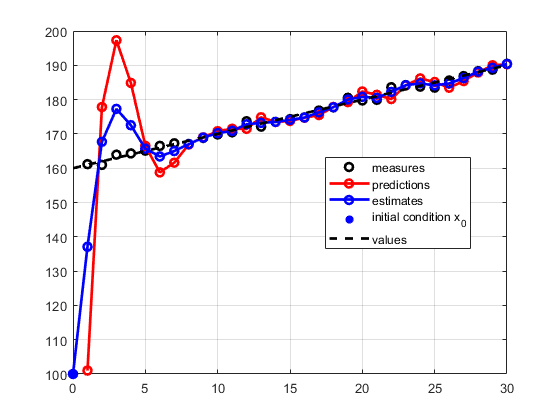

n = 30;
n0 = 160;
dt = 1;
dx = 1;
std_wn = 1;
values = dx*(0:1:n)+n0;
time = (0:1:n)*dt;

% generate measures
measures = generate_measures(n0,dx,n,std_wn);

% initial conditions
x0 = 100;
dx0 = 1;

% filter parameters
% g parameter:
% low g     ->      follow predictions
% high g    ->      follow measures
% h parameter:
% low h     ->      follow predictions velocity change
% high h    ->      follow measures velocity change

% g=6/10;
% h=2/3;
g = 0.6;
h = 0.66;

[predictions,estimates] = g_h_filter(measures,x0,dx0,g,h,dt);

plot_gh_filter(measures,predictions,estimates,values,time,x0)